# Brain street view example script 

## Define paths and parameters

#### Define where to save your data and where your Allen Atlas data is located

saveLocation = '/home/julie/Dropbox/Data/AllenQueries'; % where to save the data downloaded from the Allen Connectivity dataset 
allenAtlasPath =  '/home/julie/Dropbox/Atlas/allenCCF'; % download from: https://figshare.com/articles/dataset/Modified_Allen_CCF_2017_for_cortex-lab_allenCCF/25365829 
fileName = ''; % leave empty to recompute each time (e.g. load the Allen raw data and sumnmarize it into one matrix), 
    % or enter text (e.g. fileName = 'Visual_projections') to save and reload

#### Input information about the regions and experiments you want to plot 

inputRegions = {'CEAm'}; % region(s), use Allen Atlas abbreviation conventions (see the svc file structure_tree_safe_2017 and the column `acronym` at your allenAtlasPath)
    % or if you already have experiment IDs , skip step 1 below and input
    % them directly in step 2
mouseLine = ''; % leave empty to include all. use allen mouse line ids. 0 = wild-type. 
primaryInjection = true; % boolean, search for injections where 'injection' was the primary or not

## Get all Allen connectivity experiments of interest 

experimentIDs = bsv.findConnectivityExperiments(inputRegions, mouseLine, primaryInjection);

Found 283 experiments in VISp 
Found 68 experiments in VISl 
Found 18 experiments in VISal 
Found 38 experiments in VISam 
Found 15 experiments in VISpl 
Found 28 experiments in VISpm 
Found 14 experiments in VISli 
Found 36 experiments in VISpor 


## Fetch/load experiment data 

subtractOtherHemisphere = false;
loadAll = true; % if true, will load a 132 x 80 x 114 x number of experiments matrix instead of 132 x 80 x 114.
normalizationMethod = 'injectionVolume'; %  can be 'none', 'injectionIntensity' or 'injectionVolume'
groupingMethod = ''; % leave empty or 'NaN' to average images all together. Other options include averaging by
% 'brainRegion', 'AP', 'ML', 'DV'

[experimentImgs, injectionSummary, experimentImgs_perExperiment] = bsv.fetchConnectivityData(experimentIDs, saveLocation, fileName, normalizationMethod,...
    subtractOtherHemisphere, groupingMethod, allenAtlasPath, loadAll);

## Plot projection data (in 2D) 

#### Define your plotting parameters

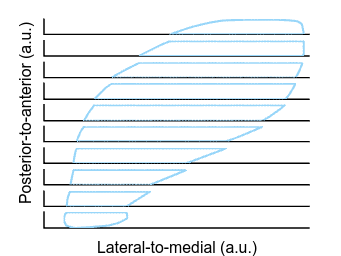

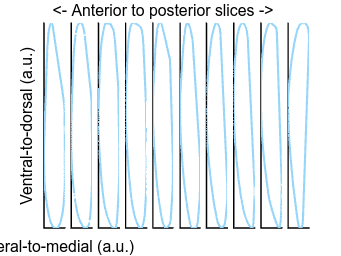

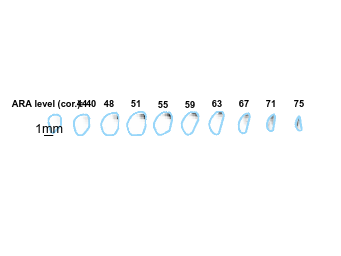

numberOfSlices = 10; % for plotting purposes: divide target (output) structure into this many slices
numberOfPixels = 15; % for plotting purposes: divide each slice in target region in numberOfPixels x numberOfPixels
outputRegions = {'CP'}; % target region of interest


% future features - these are not implemented yet, are place holders for
    % future things to come
color = [0.543,0, 0; ...
    0, 0.746, 1;...
    0.180,0.543,0.340;...
    1,0.547,0]; % - not implemented yet - outline color for each region in RGB. leave empty to use defaults 
plane = 'coronal'; % - not implemented yet - coronal or sagital
smoothing = 2; % - not implemented yet - none or a number (of pixels)
colorLimits = 'global'; % - not implemented yet - global, per slice or two numbers  
regionOnly = true; % - not implemented yet - whether to plot only one region or whole slices of the brain

#### Plot!

bsv.plotConnectivity(experimentImgs, allenAtlasPath, outputRegions, numberOfSlices, numberOfPixels, plane, regionOnly, smoothing, colorLimits, color);

## Plot injections

**2D, region by region**

Warning: This will generate a lot of plots if you have several injection regions (3 plots/region).

for iInputRegion = 1:size(inputRegions,2)
    bsv.plotConnectivity(experimentImgs, allenAtlasPath, inputRegions(iInputRegion), numberOfSlices, numberOfPixels, plane, regionOnly, smoothing, colorLimits, color);
end

#### 3D, all regions

Warning: the dot size here is not reflective of the true injection volume, it is just for visualization purposes. 

At least one END is missing. The statement beginning here does not have a matching end.

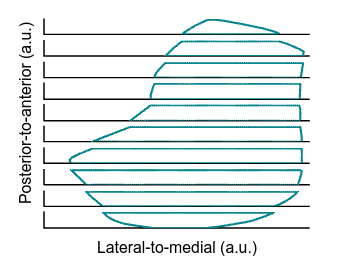

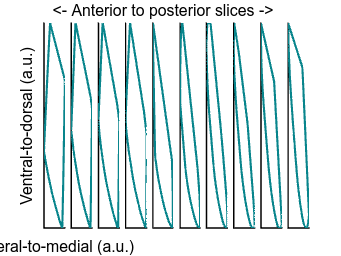

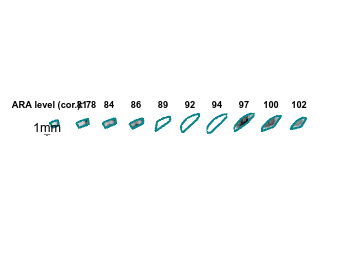

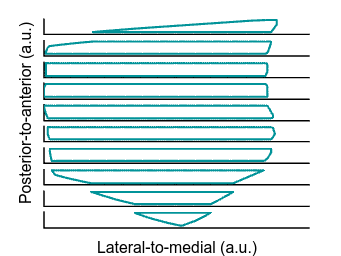

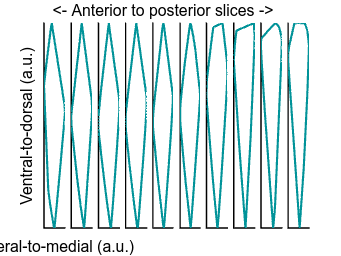

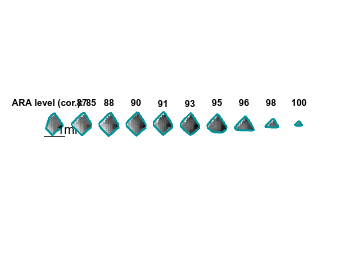

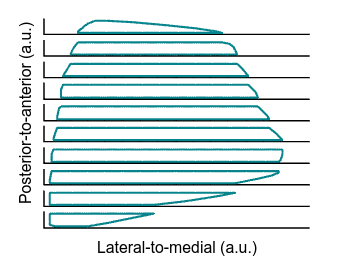

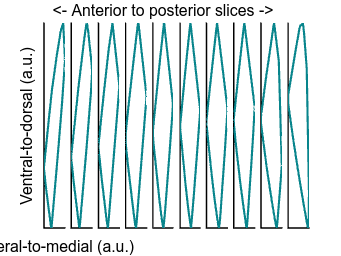

plotPatch = true; % if true plots a full volume; if false, plots a grid
bsv.plotConnectivity3D(injectionSummary, allenAtlasPath, outputRegions(1), color, plotPatch);